# Detect and Plot Water Level Change with USB Webcam Live Editor Task

This example shows you how to set up your USB webcam to detect and plot the change in water level. Interactively capture images from a USB webcam using the [Acquire Webcam Image](docid:usbwebcams_ug#mw_cf7128de-a33d-4dc5-9260-96f761e1b97d) task in the Live Editor. For more information on Live Editor tasks, see [Add Interactive Tasks to a Live Script](https://www.mathworks.com/help/matlab/matlab_prog/add-live-editor-tasks-to-a-live-script.html). 

In this example, you will estimate the level of water in a cup using image subtraction to subtract sample images from a reference image. You will also plot the normalized water levels in real-time. Use the [Acquire Webcam Image](docid:usbwebcams_ug#mw_cf7128de-a33d-4dc5-9260-96f761e1b97d) task in a loop to capture the sample images.

## Load Reference Image

This example uses the reference image `image01.png`. 

refImage = double(imread("image01.png"));

This image is of an empty glass with a resolution of 640 x 480. 

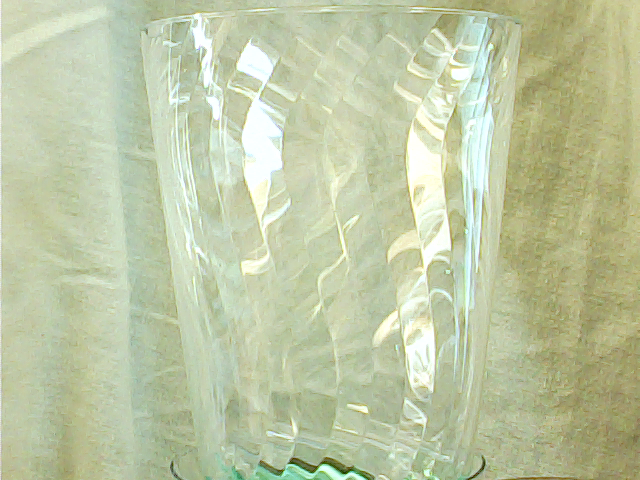

Alternatively, you can capture this image using the [Acquire Webcam Image](docid:usbwebcams_ug#mw_cf7128de-a33d-4dc5-9260-96f761e1b97d) task.

## Set up Output Window

Set up the figure to plot the water level changes in real time. 

fig = figure("Name","Water Level Tracker","Visible","off");
ax1 = subplot(2,2,1);
ax2 = subplot(2,2,3);
ax3 = subplot(2,2,[2,4]); grid on;
h = animatedline(ax3,"Color","red","LineWidth",3);

## Plot Water Level Change 

To determine the change in water level, use image subtraction. Subtract each sample image from the reference image. To capture the sample images`,`use the [Acquire Webcam Image](docid:usbwebcams_ug#mw_cf7128de-a33d-4dc5-9260-96f761e1b97d) task.

Ensure the following in the Live Task:

- Select a webcam from the webcams connected to your computer. 

- Clear the **Show image **check box to prevent displaying the image in each loop iteration.

- Turn off the Autorun feature if you want the live task to execute only when the entire script is executed. To disable autorun, click the autorun    icon.

- Select **Live preview **to view the live video from the webcam while adjusting webcam properties.

Do the following: 

- Capture images using the [Acquire Webcam Image](docid:usbwebcams_ug#mw_cf7128de-a33d-4dc5-9260-96f761e1b97d) task in a loop. You can vary the time for which the loop executes by entering the time in seconds in the textbox. 

- Subtract each `sampleImage` from the `refImage` to get the `diffImage. `

- Extract the the RGB components from `diffImage` and convert the image to grayscale to reduce the noise in the image.

- Find the mean pixel intensity value across each row of the image. The mean pixel intensity is used to find the image pixel corresponding to the top of the water level.

- Define a window size and a threshold for the intensity by moving the slider. 

- Find the difference in the instensities between the n+10th pixel and nth pixel in the `windowSize`. 'n' is the row index and 10 is the window size used in this example. If the intensity of the pixel value is greater than the threshold intensity, store the pixel value as the water level.  

- Plot the water level against time.

% Start time-stamp timer for plotting water level against time
t = tic;

while(toc(t) < 180)
   % Read the image captured from the webcam
  

% Connect to selected webcam
cam = webcam("Lenovo EasyCamera",...
	"Resolution","640x480",...
	"Brightness",0,...
	"Contrast",0,...
	"Saturation",0,...
	"Hue",0,...
	"Gamma",4,...
	"Sharpness",7,...
	"WhiteBalanceMode","auto",...
	"Gain",29,...
	"BacklightCompensation",1);

% Acquire webcam image
img = snapshot(cam);

% Clear existing webcam connection
clear cam
    sampleImage = double(img);
    
    % Store the relative timestamp
    tStamp = toc(t);
    
    % Subtract the sample image from the reference image
    diffImage = refImage - sampleImage;
    dims = size(diffImage);
    
    % Extract RGB components from the difference image
    R = uint8(diffImage(:,:,1));
    G = uint8(diffImage(:,:,2));
    B = uint8(diffImage(:,:,3));
    
    % Convert the difference image to grayscale
    greyDiffImage = zeros(dims(1),dims(2),'uint8');
    for row = 1:dims(1)
        for col = 1:dims(2)
            greyDiffImage(row,col) = (0.2989 * R(row,col)) + (0.5870 * G(row,col)) + (0.1140 * B(row,col));
        end
    end
    
    % Find mean pixel intensity value across each row of the image
    rowMean = [];
    for row = 1: dims(1)
        rowMean = [rowMean mean(greyDiffImage(row,:))];
    end
    
    % Find the image pixel corresponding to the top of water level
    % Find the difference instesities between the n+10th and nth pixel.
    % Store this pixel value as the water level, if this intesnity is greater than a threshold
    windowSize = 10;
    intensityThreshold = 15;
    waterLevelPixel = dims(1);
    for rowIndex = 1:length(rowMean)-windowSize
        if rowMean(rowIndex+windowSize) - rowMean(rowIndex) > intensityThreshold
            waterLevelPixel = rowIndex;
            break;
        end
    end
        
    % Display images
    
    % Display the reference image
    subplot(2,2,1);imshow(uint8(refImage)); hold on;
    title("Reference Image");
    
    % Display the current water level
    subplot(2,2,3);
    imshow(uint8(sampleImage)); 
    hold on;
    quiver(dims(2)/2,waterLevelPixel,0,dims(1)-waterLevelPixel,...
        "Color","yellow","LineWidth",3);
    hold off;
    title("Water Level");
    
    % Plot water level vs/ time
    subplot(2,2,[2,4]);
    title('Water level v/s Time');
    xlabel('Time (in s)');
    ylabel('Water level (normalized)');
    addpoints(h,tStamp,abs(1 - (waterLevelPixel/dims(1))));
    drawnow;
    
    fig.Visible = "on"';
end

*Copyright 2020 The MathWorks, Inc.*